Gaussian pulse with $A=2^{1/2} \sigma^{-1/2} \pi^{-1/4}$for unit energy:


$$g\left(t\right)=A\;\exp \left\lbrack \frac{-t^2 }{2\sigma^2 }\right\rbrack$$



$$G\left(f\right)=A\;\exp \left\lbrack \frac{-f^2 \sigma^2 }{2}\right\rbrack$$


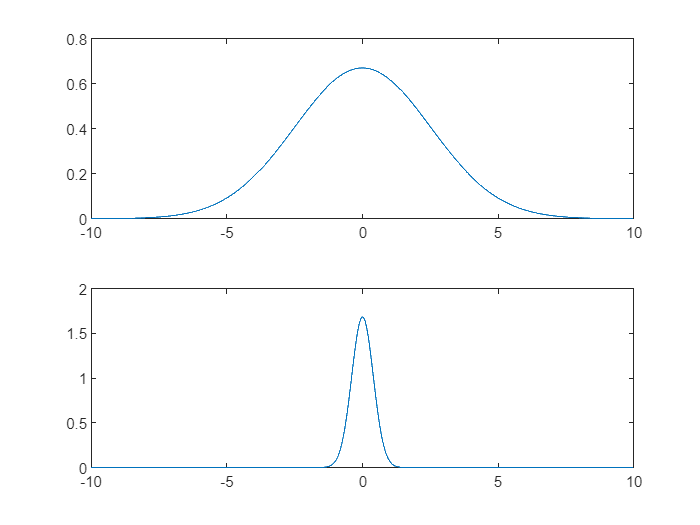

log_sigma = 0.4;sigma = 10^log_sigma;
A = @(sigma) sqrt(2)*(sigma^(-1/2))*(pi^(-1/4));
g = @(t,sigma) A(sigma) .* exp((-t.^2)/(2*sigma^2));
t = linspace(-10,10,10001); figure;
subplot(2,1,1); plot(t,g(t,sigma))
subplot(2,1,2); plot(t,g(t,1/sigma))

Pair of Gaussian pulses separated by distance $2T_0 \to$ Gaussian pulse modulated by sinusoid


$$x\left(t\right)=g\left(t-T_0 \right)+g\left(t+T_0 \right)$$



$$X\left(f\right)=G\left(f\right)\;\cos \left(2\pi T_0 f\right)$$


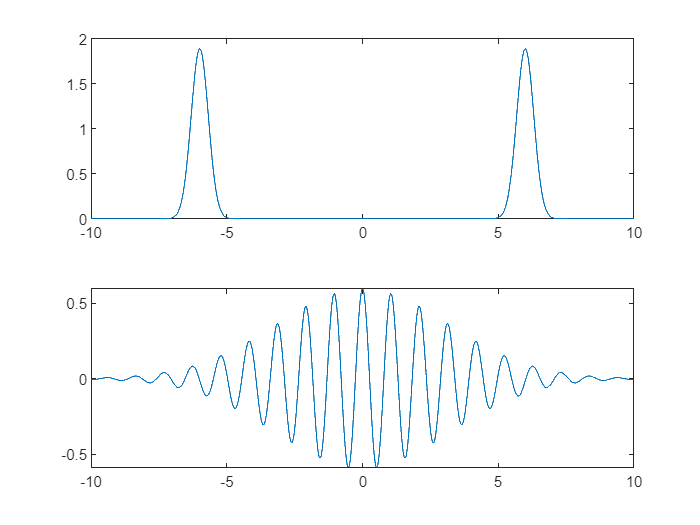

x = @(t,sigma,T0) g(t-T0,sigma) + g(t+T0,sigma);
X = @(f,sigma,T0) g(f,1/sigma).*cos(T0*f);
log_sigma = -0.5;sigma = 10^log_sigma;
T0 = 6;
figure;
subplot(2,1,1); plot(t,x(t,sigma,T0))
subplot(2,1,2); plot(t,X(t,sigma,T0))

Sequence of $n$ pulses:


$$y\left(t\right)=g\left(t\right)+\sum_{k=0}^n g(t-kT_0 )+g(t+kT_0 )$$


What does $Y\left(f\right)$ look like As $n\to \infty \;$?

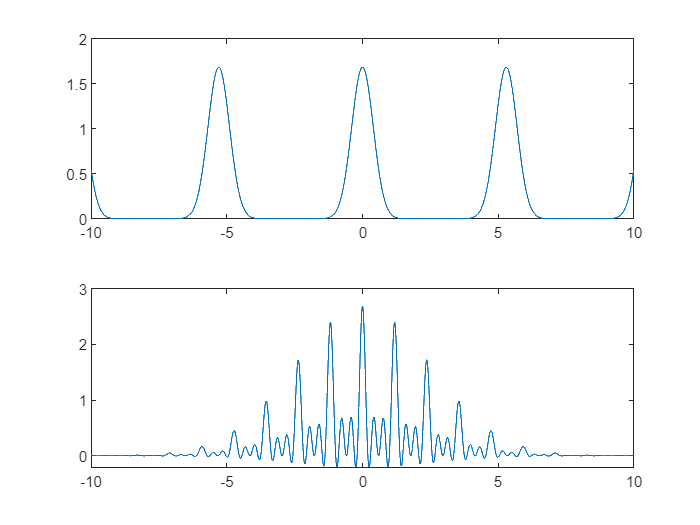

Y = 0

figure;
log_sigma = -0.4;sigma = 10^log_sigma;
T0 = 5.3;
n = 7;
subplot(2,1,1); plot(t,seq_of_pulses(t,sigma,T0,n))
subplot(2,1,2); plot(t,FT(t,sigma,T0,n))

function y = seq_of_pulses(t,sigma,T0,n)
    n = (n-1)/2;
    A = @(sigma) sqrt(2)*(sigma^(-1/2))*(pi^(-1/4));
    g = @(t,sigma) A(sigma) .* exp((-t.^2)/(2*sigma^2));
    y = g(t,sigma);
    for k = 1:n
        y = y + g(t-k*T0,sigma) + g(t+k*T0,sigma);
    end
end

function Y = FT(f,sigma,T0,n)
    n = (n-1)/2;
    A = @(sigma) sqrt(2)*(sigma^(-1/2))*(pi^(-1/4));
    g = @(t,sigma) A(sigma) .* exp((-t.^2)/(2*sigma^2));
    Y = 0
    for k = 0:n
        Y = Y + g(f,1/sigma).*cos(k*T0*f);;
    end
end